# AB-271: Lista discretização espacial

**Reynaldo Lima**

## Exercício 1

Temos a equação:


$$u_t(x,t)=u_{xx}(x,t),\\u(0,t)=u(L,t)=0,\\u(x,0)=u_0(x).$$


Seja, pois, $u\left(x,t\right)=\phi \;{\left(x\right)}^T y\left(t\right)$, e um vetor auxiliar qualquer dado por $v^T \phi \;\left(x\right)\ldotp$

Obtemos, na equação original:


$$v^T\left[\int_0^L \phi \phi^T dx \right] \dot{y}=v^T\left[\int_0^L \phi \phi_{xx}^T dx \right]y.$$


Fazendo $M = \left[\int_0^L \phi \phi^T dx \right], D = \left[\int_0^L \phi \phi_{xx}^T dx \right]$, temos:

$\dot{y}=M^{-1}Dy$.

$\dot{\;u} =\phi \;{\left(x\right)}^T \dot{\;y}$.

Temos agora uma EDO no tempo, o que nos permite fazer uma simulação com esta expressão.

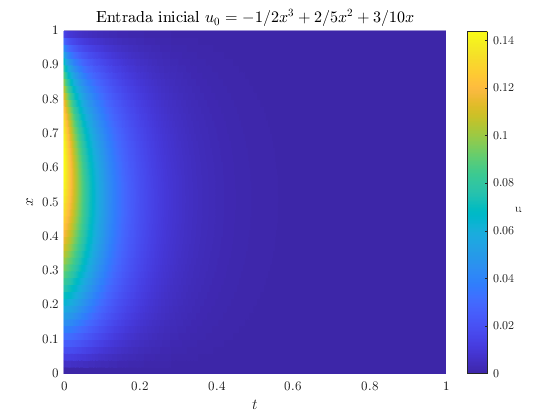

% Escolhendo as funções phi
% Das condições de contorno, vale escolhermos:
clear;
syms x;
L = 1; % comprimento, normalizado para 1 apenas para a sim.
n = 5;
v = [];
for i = 1:n
    v = [v; x^i];
end
phi = v*(L-x);
dphi = diff(phi,x);
ddphi = diff(dphi, x);
M = double(int(phi*transpose(phi),0,L));
D = double(int(phi*transpose(ddphi),0,L));
A = M\D;
syms t u;
y = sym('y', [n;1]);
eq = [A zeros(n,1); transpose(phi)*A 0]*[y;u];
di = matlabFunction(eq, 'Vars', {t, [y; u], x});
u_0 = @(x) 0.5*x^2*(L-x) + 0.3*x*(L-x);
% função inicial conhecida, para forçar o y(0)
for i = 1:51
x0 = (i-1)/50;
u0 = u_0(x0);
[T,Y(i,:,:)]=ode45(@(t,X) di(t,X,x0),[0,1],[0.3;0.5;zeros(n-2,1);u0]);
end
figure(1);
surf(T,0:1/50:1,Y(:,:,n+1),'EdgeColor',"flat")
h = colorbar;
ylabel(h, 'u', 'Interpreter',"latex", 'Rotation',pi/2);
view(2);
xlabel('$t$', 'Interpreter',"latex")
zlabel('$u$', 'Interpreter',"latex")
ylabel('$x$', 'Interpreter',"latex")
set(gca,'TickLabelInterpreter','latex');
set(h,'TickLabelInterpreter','latex');
title('Entrada inicial $u_0 = - 1/2 x^3 + 2/5 x^2 + 3/10 x$', 'FontSize', 12, 'Interpreter',"latex")

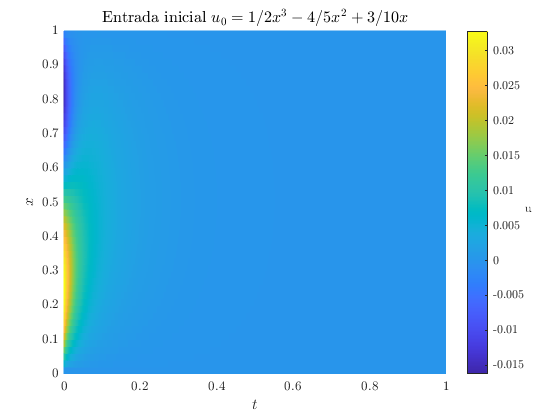



u_0 = @(x) -0.5*x^2*(L-x) + 0.3*x*(L-x);
% função inicial conhecida, para forçar o y(0)
for i = 1:51
x0 = (i-1)/50;
u0 = u_0(x0);
[T,Z(i,:,:)]=ode45(@(t,X) di(t,X,x0),[0,1],[0.3;-0.5;zeros(n-2,1);u0]);
end
figure(2);
surf(T,0:1/50:1,Z(:,:,n+1),'EdgeColor',"flat")
h = colorbar;
ylabel(h, 'u', 'Interpreter',"latex", 'Rotation',pi/2);
view(2);
xlabel('$t$', 'Interpreter',"latex")
zlabel('$u$', 'Interpreter',"latex")
ylabel('$x$', 'Interpreter',"latex")
set(gca,'TickLabelInterpreter','latex');
set(h,'TickLabelInterpreter','latex');
title('Entrada inicial $u_0 = 1/2 x^3 - 4/5 x^2 + 3/10 x$', 'FontSize', 12, 'Interpreter',"latex")

## Exercício 2

Temos:


$$\left\lbrack \begin{array}{c}
\dot{\;\alpha {\;}_1 } \left(x,t\right)\\
\dot{\;\alpha {\;}_2 } \left(x,t\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
0 & c_2 \;\partial {\;}_x \\
c_{\;2} \;\partial {\;}_x  & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\alpha {\;}_1 \left(x,t\right)\\
\alpha {\;}_2 \left(x,t\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
0 & \;\partial {\;}_x \\
\partial_x  & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
e{\;}_1 \left(x,t\right)\\
e_2 \left(x,t\right)
\end{array}\right\rbrack ,$$


com Hamiltoniano do sistema:


$$H=\int_0^L \;\left(c_1 \alpha {\;}_1^2 +c_2 \alpha {\;}_2^2 \right)\;\textrm{dx}\;\ldotp$$


Utilizando o método de Galerkin para aproximar os resultados do sistema, obedecendo as condições básicas do sistema.

Usando a formulação fraca:


$$\int_0^L v_1(x) \dot{\alpha_1}(x,t)dx = \int_0^Lv_1(x)\partial_x e_2dx = -\int_0^L(\partial_x v_1)e_2 dx + [v_1(x) e_2(x,t)]_0^L,\\
\int_0^L v_2(x) \dot{\alpha_2}(x,t)dx = \int_0^Lv_2(x)\partial_x e_1dx\.\$$


Sejam as aproximações:


$$\alpha_1(x,t)\approx a_1^T(t)\phi_1(x), \ \alpha_2(x,t)\approx a_2^T(t)\phi_2(x), \\
v_1(x,t) \approx \bar{v}_1(t)\phi_1(x), \ v_2(x,t) \approx \bar{v}_2(t)\phi_2(x), \\
e_1(x,t) \approx \epsilon_1^T(t)\phi_1(x),e_2(x,t) \approx \epsilon_2^T(t)\phi_2(x). $$


Temos:


$$\bar{v}_1^T  \underset{\mathbf{M_1}}{\left[\int_0^L\phi_1(x) \phi_1^T(x) dx \right]} \dot{a_1}(t)=-\bar{v}_1^T  \underset{\mathbf{D}}{\left[\int_0^L\phi_{1,x}(x) \phi_2^T(x) dx\right]}c_2 a_2(t) +  \underset{\mathbf{[\phi_1(L)\ -\phi_1(0)][e_2(L,t)\ e_2(0,t)]^T}}{\bar{v}_1^T \phi_1(x) e_2 (x,t)|^L_0},$$



$$\bar{v}_2 \underset{\mathbf{M_2}}{ \left[\int_0^L \phi_2 (x) \phi_2^T(x)dx \right]}\dot{a}_2(t) = \bar{v}_2 \underset{\mathbf{D^T}}{ \left[\int_0^L \phi_2 (x) \phi_{1,x}^T(x) dx \right] }c_1 a_1(t).$$


 Como as expressões são válidas para vetores $v_i$ quaisquer, $i=1,2$, escolhendo como saída $y_{\partial \;} ={\left\lbrack e_1 \left(L,t\right)\;\;-e_1 \left(0,t\right)\right\rbrack }^T$, vale as expressões a seguir, em que omitem-se as dimensões das matrizes de zeros satisfatórias para as dimensões do problema:


$$x\left(t\right):=\left\lbrack \begin{array}{c}
M_1 \;a_1 \left(t\right)\\
M_2 \;a_2 \left(t\right)
\end{array}\right\rbrack ,$$



$$\begin{array}{l}
\dot{\;x} \left(t\right)=\underset{\mathit{\mathbf{J}}}{\left\lbrack \begin{array}{cc}
0 & -D\\
D^T  & 0
\end{array}\right\rbrack } \underset{Q}{\left\lbrack \begin{array}{cc}
c_1 M_1^{-1}  & 0\\
0 & c_2 M_2^{-1} 
\end{array}\right\rbrack } x\left(t\right)+\underset{B}{\left\lbrack \begin{array}{cc}
\phi {\;}_1 \left(L\right) & -\phi {\;}_1 \left(0\right)\\
0 & 0
\end{array}\right\rbrack } \;u_{\partial \;} ,\\
y_{\partial \;} \left(t\right)=\underset{B^T }{{\left\lbrack \begin{array}{cc}
\phi {\;}_1 \left(L\right) & -\phi {\;}_1 \left(0\right)\\
0 & 0
\end{array}\right\rbrack }^T } \underset{Q}{\left\lbrack \begin{array}{cc}
c_1 M_1^{-1}  & 0\\
0 & c_2 M_2^{-1} 
\end{array}\right\rbrack } x\left(t\right)\ldotp 
\end{array}$$


Com essa representação do sistema, temos, para o Hamiltoniano discretizado:


$$\begin{array}{l}
H_d :=H\left\lbrack \alpha_1 \left(x,t\right)=a_1^T \left(t\right)\phi_1 \left(x\right),\alpha_2 \left(x,t\right)=a_2^T \left(t\right)\phi_2 \left(x\right)\right\rbrack \overset{{\overrightarrow{\;v} }^2 =\left|\right|\;\overrightarrow{v} \left|{\left|\right.}_2^2 \right.}{=} \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\frac{1}{2}\int_0^L \left(c_1 a_1^T \left(t\right)\phi_1 \left(x\right)\phi {\;}_1 {\left(x\right)}^T a_1 \left(t\right)+c_2 a_2^T \left(t\right)\phi_2 \left(x\right)\phi {\;}_2^T \left(x\right)a_2 \left(t\right)\right)\textrm{dx}=\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\frac{1}{2}\left(c_1 a_1^T \left(t\right)M_1 a_1 \left(t\right)+c_2 a_2^T \left(t\right)M_2 a_2 \left(t\right)\right)=\frac{1}{2}{\left\lbrack \begin{array}{c}
M_1 {\;}^T a_1 \left(t\right)\\
M_2 {\;}^T a_2 \left(t\right)
\end{array}\right\rbrack }^T Q\;x\left(t\right)\;\overset{M_1^T =M_1 }{=} \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\frac{1}{2}x^T Q\;x\ldotp 
\end{array}$$


E sua derivada temporal:


$$2\dot{\;H_d } =\frac{d}{d\;t}\left(x^T Q\right)x+x^T Q\;\frac{d}{d\;t}\left(x\right)={\dot{x} }^T Q\;x+x^T Q\;\dot{\;x} ={\dot{\;x} }^T \left(Q+Q^T \right)x\overset{Q=Q^T }{=} 2\;\dot{\;x} {\;}^T Q\;x\;,\;$$


daí:


$$\begin{array}{l}
{\dot{\;H} }_{\;d} =\left(x^T Q^T J^T Q\;x+u_{\partial }^T B^T Q\;x\;\right)=x^T \underset{Q^T }{\left\lbrack \begin{array}{cc}
c_1 M_1^{-1}  & 0\\
0 & c_2 M_2^{-1} 
\end{array}\right\rbrack } \underset{{\mathit{\mathbf{J}}}^T }{\left\lbrack \begin{array}{cc}
0 & D\\
-D^T  & 0
\end{array}\right\rbrack } \underset{Q}{\left\lbrack \begin{array}{cc}
c_1 M_1^{-1}  & 0\\
0 & c_2 M_2^{-1} 
\end{array}\right\rbrack } x+u_{\partial }^T y_{\partial } \overset{M_i^T =M_i ,i=1,2}{=} \\
\;\;\;\;\;\;\;=\left\lbrack \begin{array}{cc}
{\left(M_1 a_1 \right)}^T  & {\left(M_2 a_2 \right)}^T 
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
0 & c_1 c_2 M_1^{-1} DM_2^{-1} \\
-c_1 c_2 M_2^{-1} D^T \;M_1^{-1}  & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
M_1 \;a_1 \\
M_2 \;a_2 
\end{array}\right\rbrack +{u_{\partial } }^T y_{\partial } =\\
\;\;\;\;\;\;\;=c_1 c_2 \left(a_1^T Da_2 -a_2^T D^T \;a_1 \right)+u_{\partial }^T y_{\partial } \;=c_1 c_2 \left(\int_0^L a_1^T \;\;\phi_{1,x} \phi_2^T a_2 -{a_2 }^T \phi {\;}_2 \phi_{1,x}^T a_1 \;\;\;d\;x\right)+u_{\partial }^T y_{\partial } \;\overset{a=\textrm{escalar}\to a=v^T v=v\;v^T }{=} \\
\;\;\;\;\;\;\;=u_{\partial }^T y_{\partial } \ldotp 
\end{array}$$


Vamos agora ilustrar o problema da onda com esta formulação.

Para a simulação, sejam:

% c1 = c2 = c
c= 1;
% phi1 = phi2
L = 1;
xref = 0:L/3:L;
%yref = ;
phi = [];
syms x
for i = 1:length(xref)
    p = 1;
    for j = 1:length(xref)
        if j~=i
            aux = (x-xref(j))/(xref(i)-xref(j));
            p = p*aux;
        end
    end
    phi = [phi;p];
end
dphi = diff(phi,x);
M = double(int(phi*transpose(phi),0,L));
D = double(int(dphi*transpose(phi),0,L));
J = [zeros(length(D)) -D;D' zeros(length(D))];
Q = blkdiag(c.*inv(M),c.*inv(M));

### 2.1 Autovalores de JQ

Como estamos trabalhando com a equação da onda unidimensional, espera-se que os autovalores sejam imaginários puros (garantindo as oscilações do movimento). De fato, observa-se:

autovalores = eig(J*Q)

autovalores =   -0.0000 +13.0432i
  -0.0000 -13.0432i
   0.0000 + 7.7460i
   0.0000 - 7.7460i
  -0.0000 + 3.1425i
  -0.0000 - 3.1425i
  -0.0000 + 0.0000i
   0.0000 + 0.0000i


Observa-se ainda que estes autovalores são aproximadamente múltiplos de $\pi \ldotp$

Como as constantes são tomadas unitárias, espera-se:


$$\omega_n =\frac{2\;\pi }{2L}n\sqrt{\frac{T}{\mu }}=n\pi \ldotp$$


O primeiro teste, com 4 dimensões para a aproximação, se distancia de $n\pi$já para $n=2$. Por outro lado, observe o exemplo com 8 dimensões, que já tem até $n=5$ próximo ao previsto pela relação anterior.

% c1 = c2 = c
c= 1;
% phi1 = phi2
L = 1;
xref = 0:L/8:L;
%yref = ;
phi = [];
syms x
for i = 1:length(xref)
    p = 1;
    for j = 1:length(xref)
        if j~=i
            aux = (x-xref(j))/(xref(i)-xref(j));
            p = p*aux;
        end
    end
    phi = [phi;p];
end
dphi = diff(phi,x);
M = double(int(phi*transpose(phi),0,L));
D = double(int(dphi*transpose(phi),0,L));
J = [zeros(length(D)) -D;D' zeros(length(D))];
Q = blkdiag(c.*inv(M),c.*inv(M));
autovalores = eig(J*Q)

autovalores =   -0.0000 +57.7879i
  -0.0000 -57.7879i
   0.0000 +46.3195i
   0.0000 -46.3195i
  -0.0000 +20.5626i
  -0.0000 -20.5626i
  -0.0000 +16.6063i
  -0.0000 -16.6063i
   0.0000 +12.5800i
   0.0000 -12.5800i


### 2.2 Simulações, condições iniciais nulas, fronteira com entrada senoidal;

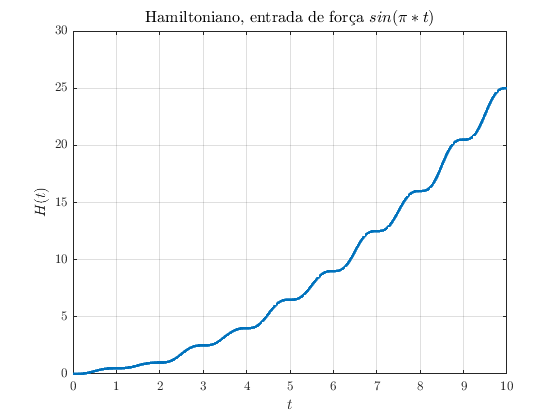

clear;
% c1 = c2 = c
c= 1;
% phi1 = phi2
L = 1;
n = 8;
xref = 0:L/(n-1):L;
%yref = ;
phi = [];
syms z
for i = 1:length(xref)
    p = 1;
    for j = 1:length(xref)
        if j~=i
            aux = (z-xref(j))/(xref(i)-xref(j));
            p = p*aux;
        end
    end
    phi = [phi;p];
end
dphi = diff(phi,z);
M = double(int(phi*transpose(phi),0,L));
D = double(int(dphi*transpose(phi),0,L));
J = [zeros(length(D)) -D;D' zeros(length(D))];
Q = blkdiag(c.*inv(M),c.*inv(M));
B = [subs(phi,L) -subs(phi,0);zeros(length(phi),1) zeros(length(phi),1)];
x = sym('x', [2*n;1]);
h = sym('h', [1;1]);
t = sym('t', [1;1]);
omega = pi;
% Condições de contorno: onda excitada em uma extremidad
% e e nula na
% outra!!!
eq = [J*Q*x + B*[sin(omega*t);0];[sin(omega*t) 0]*B'*Q*x];
di = matlabFunction(eq, 'Vars', {t, [x;h]});
x0 = zeros(2*n,1);
h0 = 0;
[T,Z]=ode45(@(t,X) di(t,X),[0,10],[x0;h0]);
figure;
plot(T,Z(:,2*n+1),'linewidth',2);
xlabel('$t$', 'Interpreter',"latex")
ylabel('$H(t)$', 'Interpreter',"latex")
set(gca,'TickLabelInterpreter','latex');
title('Hamiltoniano, entrada de for\c{c}a $sin(\pi*t)$', 'FontSize', 12, 'Interpreter',"latex")
grid on;

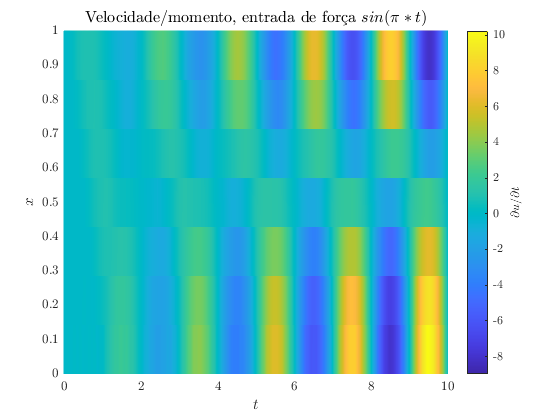

a1 = transpose(subs(phi,0:L/(n-1):L))*inv(M)*Z(:,1:n)';
a2 = transpose(subs(phi,0:L/(n-1):L))*inv(M)*Z(:,n+1:2*n)';

figure;
surf(T,0:L/(n-1):L,double(a1),'EdgeColor',"flat")
h = colorbar;
ylabel(h, '$\partial u/\partial t$', 'Interpreter',"latex");
view(2);
xlabel('$t$', 'Interpreter',"latex")
%zlabel('$y$', 'Interpreter',"latex")
ylabel('$x$', 'Interpreter',"latex")
title('Velocidade/momento, entrada de for\c{c}a $sin(\pi*t)$', 'FontSize', 12, 'Interpreter',"latex")
set(gca,'TickLabelInterpreter','latex');
set(h,'TickLabelInterpreter','latex');

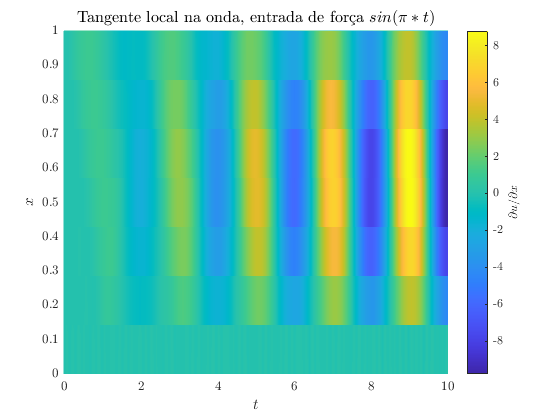


figure;
surf(T,0:L/(n-1):L,double(a2),'EdgeColor',"flat")
h = colorbar;
ylabel(h, '$\partial u/\partial x$', 'Interpreter',"latex");
view(2);
xlabel('$t$', 'Interpreter',"latex")
%zlabel('$y$', 'Interpreter',"latex")
ylabel('$x$', 'Interpreter',"latex")
set(gca,'TickLabelInterpreter','latex');
title('Tangente local na onda, entrada de for\c{c}a $sin(\pi*t)$', 'FontSize', 12, 'Interpreter',"latex")
set(h,'TickLabelInterpreter','latex');

### 2.3 Damping injection

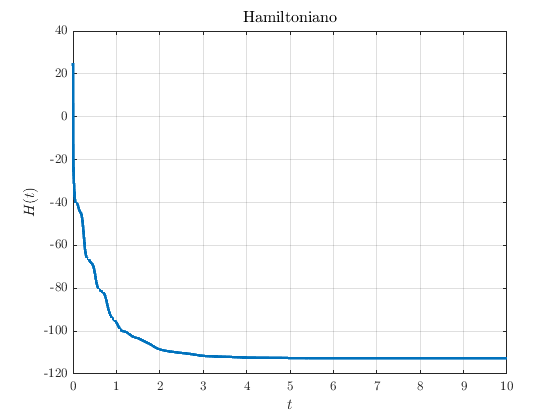

clear;
% c1 = c2 = c
c= 1;
% phi1 = phi2
L = 1;
n = 8;
xref = 0:L/(n-1):L;
%yref = ;
phi = [];
syms z
for i = 1:length(xref)
    p = 1;
    for j = 1:length(xref)
        if j~=i
            aux = (z-xref(j))/(xref(i)-xref(j));
            p = p*aux;
        end
    end
    phi = [phi;p];
end
dphi = diff(phi,z);
M = double(int(phi*transpose(phi),0,L));
D = double(int(dphi*transpose(phi),0,L));
J = [zeros(length(D)) -D;D' zeros(length(D))];
Q = blkdiag(c.*inv(M),c.*inv(M));
B = [subs(phi,L) -subs(phi,0);zeros(length(phi),1) zeros(length(phi),1)];
x = sym('x', [2*n;1]);
h = sym('h', [1;1]);
t = sym('t', [1;1]);
omega = pi;
% Condições de contorno: regulador e condições iniciais unitárias
% Vamos ver como ele sai de um impulso!!
% outra!!!
k = pi;
y = B'*Q*x;
u = -k*y;
eq = [J*Q*x + B*u;u'*y];
di = matlabFunction(eq, 'Vars', {t, [x;h]});
x0 = ones(2*n,1);
h0 = n*k;
[T,Z]=ode45(@(t,X) di(t,X),[0,10],[x0;h0]);
figure;
plot(T,Z(:,2*n+1),'linewidth',2);
title('Hamiltoniano', 'FontSize', 12, 'Interpreter',"latex")
xlabel('$t$', 'Interpreter',"latex")
ylabel('$H(t)$', 'Interpreter',"latex")
set(gca,'TickLabelInterpreter','latex');
grid on;

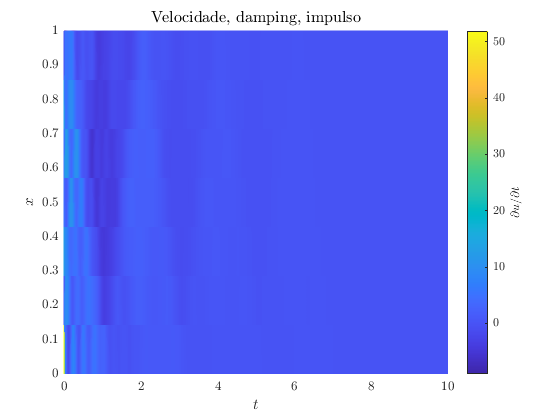

a1 = transpose(subs(phi,0:L/(n-1):L))*inv(M)*Z(:,1:n)';
a2 = transpose(subs(phi,0:L/(n-1):L))*inv(M)*Z(:,n+1:2*n)';

figure;
surf(T,0:L/(n-1):L,double(a1),'EdgeColor',"flat")
h = colorbar;
ylabel(h, '$\partial u/\partial t$', 'Interpreter',"latex");
view(2);
xlabel('$t$', 'Interpreter',"latex")
%zlabel('$y$', 'Interpreter',"latex")
ylabel('$x$', 'Interpreter',"latex")
title('Velocidade, damping, impulso', 'FontSize', 12, 'Interpreter',"latex")
set(gca,'TickLabelInterpreter','latex');
set(h,'TickLabelInterpreter','latex');

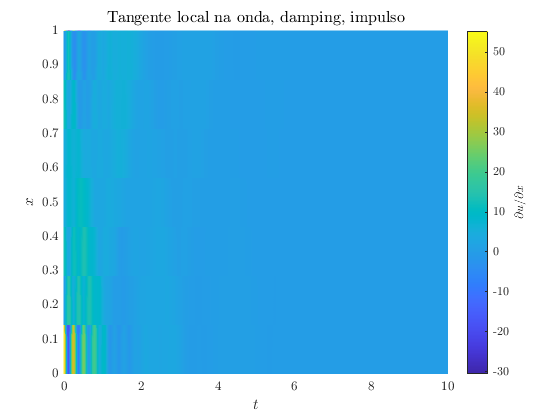


figure;
surf(T,0:L/(n-1):L,double(a2),'EdgeColor',"flat")
h = colorbar;
ylabel(h, '$\partial u/\partial x$', 'Interpreter',"latex");
view(2);
xlabel('$t$', 'Interpreter',"latex")
%zlabel('$y$', 'Interpreter',"latex")
ylabel('$x$', 'Interpreter',"latex")
title('Tangente local na onda, damping, impulso', 'FontSize', 12, 'Interpreter',"latex")
set(gca,'TickLabelInterpreter','latex');
set(h,'TickLabelInterpreter','latex');

## Exercício 3

Escolhendo formular o problema com restrições na saída. Para o nosso teste, vamos adotar: $y=\left\lbrack \begin{array}{c}
e_1 \left(L,t\right)\\
{-e}_1 \left(0,t\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
e_1 \left(L,t\right)\\
0
\end{array}\right\rbrack$,

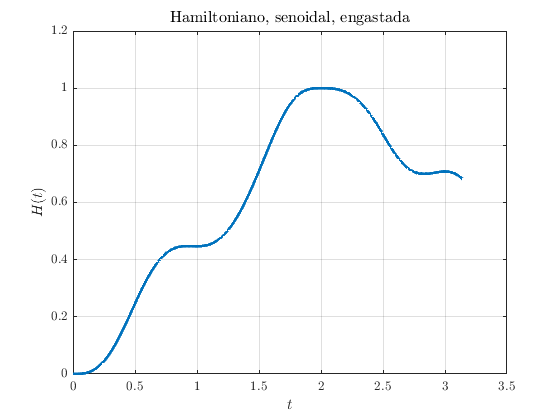

clear;
% c1 = c2 = c
c= 1;
% phi1 = phi2
L = 1;
n = 31;
xref = 0:L/(n-1):L;
%yref = ;
phi = [];
syms z
for i = 1:length(xref)
    p = 1;
    for j = 1:length(xref)
        if j~=i
            aux = (z-xref(j))/(xref(i)-xref(j));
            p = p*aux;
        end
    end
    phi = [phi;p];
end
dphi = diff(phi,z);
M = double(int(phi*transpose(phi),0,L));
D = double(int(dphi*transpose(phi),0,L));
J = [zeros(length(D)) -D;D' zeros(length(D))];
Q = blkdiag(c.*inv(M),c.*inv(M));
B = [subs(phi,L) -subs(phi,0);zeros(length(phi),1) zeros(length(phi),1)];
x = sym('x', [2*n;1]);
h = sym('h', [1;1]);
t = sym('t', [1;1]);
omega = pi;
% Saída nula na origem, entrada senoidal na extremidade
omega = pi;
y = B'*Q*x;
y(2) = 0; % e1 = c1 alpha1 -> alpha1 -> x(1:n) ctt de valor inicial zero
eq = [0;J(2:2*n,2:2*n)*Q(2:2*n,2:2*n)*x(2:2*n) + B(2:end,:)*[sin(omega*t);0];[sin(omega*t) 0]*y];
di = matlabFunction(eq, 'Vars', {t, [x;h]});
x0 = zeros(2*n,1);
h0 = 0;
[T,Z]=ode45(@(t,X) di(t,X),[0,pi],[x0;h0]);


figure;
plot(T,Z(:,2*n+1),'linewidth',2);
xlabel('$t$', 'Interpreter',"latex")
ylabel('$H(t)$', 'Interpreter',"latex")
set(gca,'TickLabelInterpreter','latex');
title('Hamiltoniano, senoidal, engastada', 'FontSize', 12, 'Interpreter',"latex")
grid on;

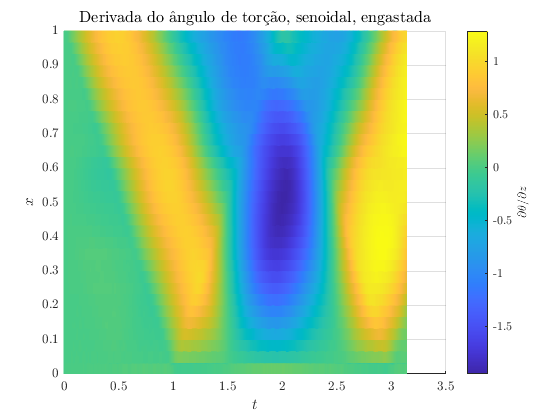


a1 = transpose(subs(phi,0:L/(n-1):L))*inv(M)*Z(:,1:n)';
a2 = transpose(subs(phi,0:L/(n-1):L))*inv(M)*Z(:,n+1:2*n)';

figure;
surf(T,0:L/(n-1):L,double(a1),'EdgeColor',"flat")
h = colorbar;
ylabel(h, '$\partial \theta/\partial z$', 'Interpreter',"latex");
view(2);
xlabel('$t$', 'Interpreter',"latex")
%zlabel('$y$', 'Interpreter',"latex")
ylabel('$x$', 'Interpreter',"latex")
title('Derivada do \^{a}ngulo de tor\c{c}\~{a}o, senoidal, engastada', 'FontSize', 12, 'Interpreter',"latex")
set(gca,'TickLabelInterpreter','latex');
set(h,'TickLabelInterpreter','latex');

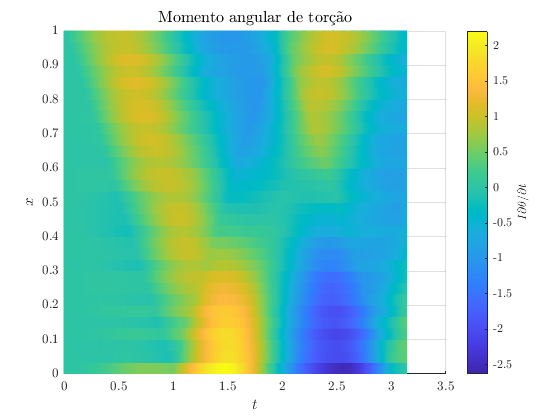


figure;
surf(T,0:L/(n-1):L,double(a2),'EdgeColor',"flat")
h = colorbar;
ylabel(h, '$I \partial \theta/\partial t$', 'Interpreter',"latex");
view(2);
xlabel('$t$', 'Interpreter',"latex")
%zlabel('$y$', 'Interpreter',"latex")
ylabel('$x$', 'Interpreter',"latex")
set(gca,'TickLabelInterpreter','latex');
title('Momento angular de tor\c{c}\~{a}o', 'FontSize', 12, 'Interpreter',"latex")
set(h,'TickLabelInterpreter','latex');